% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear

% Please be advised this section is another experiment.

r=0.5; % geometric series constant
axRatio = 2; %the ratio amax/xmax
eps = 2; % the privacy parameter
delta = 0; % privacy parameter

% filename = sprintf("estimated_freq_2_GAUSSIAN_100000_-5_5_1_0.1_0.25.csv");
% x_P = readmatrix(filename);
% x_P = x_P'./ sum(x_P);
% M = length(x_P); % Total number of bins in [-xmax,xmax]

M = 15;
xmax = 1;
xmin = -xmax;
x_bin_size = (xmax-xmin)/M;
x_grid = linspace(xmin+0.5*x_bin_size,xmax-0.5*x_bin_size,M);

% x_P = x_grid+xmax;
% x_P = ones(1,M)/M; % Uniform distribution for testing
sigma = 0.2

sigma = 0.2000

x_P = exp(-x_grid.^2/2/sigma^2);
% x_P = exp(-4*x_grid)
x_P = x_P./ sum(x_P);


[varVector,pMatrix,a_grid] =...
    opt_variance(eps,delta,r,axRatio,x_grid,x_P);

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0322   -0.0607    0.0596    0.2754   -0.0203   -0.0453   -0.0043   -0.0278    0.0502    0.1162   -0.0139    0.0799    0.0609   -0.1654   -0.0032


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.9680    0.9324    0.8649    0.7760    0.6743    0.5534    0.4823    0.4823    0.4823    0.5534    0.6743    0.7760    0.8649    0.9324    0.9680


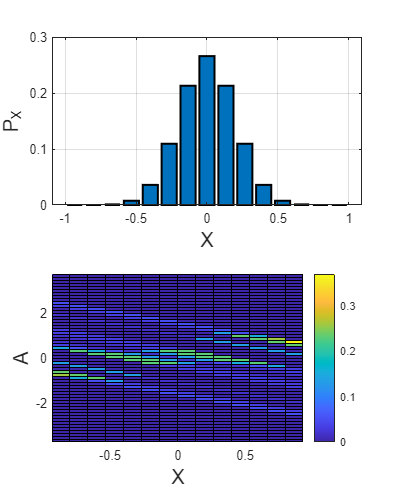

filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_pMatrix.csv', axRatio,xmax,eps,delta);
writematrix(pMatrix,filename,'Delimiter','comma');
% filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_xGrid.csv', axRatio,xmax,eps,delta);
% writematrix(x_grid,filename,'Delimiter','comma');
% filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_aGrid.csv', axRatio,xmax,eps,delta);
% writematrix(a_grid,filename,'Delimiter','comma');

% The plots

figure;
f = figure;
f.Position = [0 0 400 500];
subplot(2,1,1)
bar(x_grid,x_P,LineWidth=1.5);
xlabel("X",'FontSize',15);
ylabel("P_X",'FontSize',15);
grid on

subplot(2,1,2)
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
pcolor(X_grid,Y_grid,pMatrix');
xlabel("X",'FontSize',15);
ylabel("A",'FontSize',15);
colorbar
zlabel("P(A|X=x)",'FontSize',15);

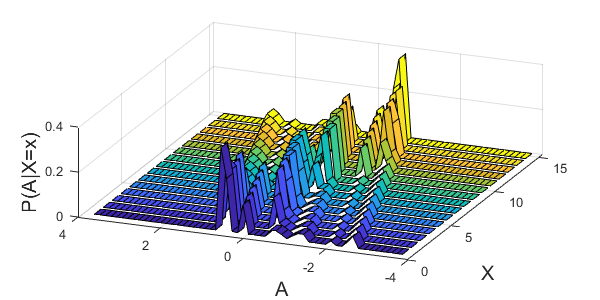


figure;
f = figure;
f.Position = [0 0 600 300];
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
ribbon(Y_grid,pMatrix');
xlabel("X",'FontSize',15);
ylabel("A",'FontSize',15);
zlabel("P(A|X=x)",'FontSize',15);